# MATLAB XR Example

*Copyright 2024 The MathWorks, Inc.*

This is a demo of MATLAB interactive immersive experience in an extended reality (XR) environment using the WebXR toolkit.

In this demo we show how to create a Graphics Library Transmission Format (GLTF) asset by generating the vertices and faces for a MATLAB surface plot.

Then we show how to load the generated 3D model to the XR environment using WebXR toolkit.

3rd time is a charm! jt

# Create a surface plot

Here we have shown an example surface plot. You can refer to several other examples for surface, stem, plot3, mesh, histogram, contour, bar, scatter, ... in the samples folder. 

We have used cmap to hold the colormap of the surface plot for saving in the GLTF asset. Note that this step is optional for getting same colors in GLTF compared to the MATLAB figure object.

[X,Y] = meshgrid(-5:.2:5);
Z = 0.5*Y.*sin(X) - 0.5*X.*cos(Y);
figure;
s = surf(X,Y,Z);
cmap = colormap;
cmin = min(s.CData(:));
cmax = max(s.CData(:));
m = length(cmap);
index = fix((s.CData-cmin)/(cmax-cmin)*(m-1))+1; %A
RGB = ind2rgb(index,cmap);

# Generate Graphics Library Transmission Format (GLTF) asset

This section uses the faces, vertices and color data from MATLAB surf2patch command to create the glTF file.

This section is inspired by a File Exchange package "[GLTF for MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/123955-gltf-for-matlab)" from [Rohan Chabukswar](https://www.mathworks.com/matlabcentral/profile/authors/5473992).

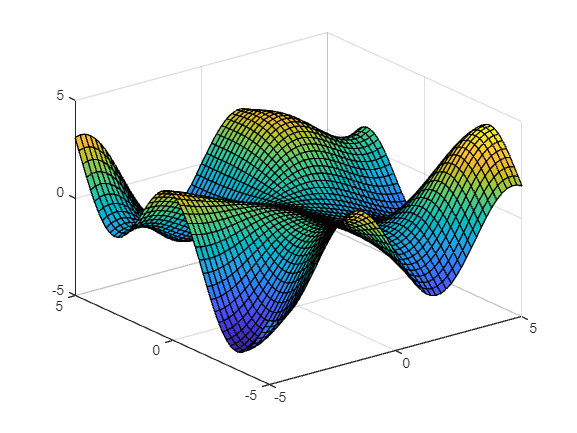

addpath('functions') 
% Get the faces, vertices, and the corresponding colours.
% Use triangles as GLTF only supports triangular faces.
[F,V,C]=surf2patch(X,Y,Z,RGB,'triangles');
% Get the rectangular faces that MATLAB would use. We will use these to
% create edges.
[E,~]=surf2patch(X,Y,Z);
% Create the list of edges. For example, for Face 1 2 3 4, edges are 1-2,
% 2-3, 3-4, and 4-1.
E=reshape(E(:,[1 2 2 3 3 4 4 1])',2,[])';
% Since the direction of the edge doesn't matter, we sort it so the
% lower-indexed vertex is first.
E=sort(E,2); %#ok<UDIM>
% This enables us to discard duplicate edges.
E=unique(E,'rows');
% Scale vertices based on data aspect ratio and plot aspect ratio to make
% the 3D Object look as much like the MATLAB plot as possible.
V=V./daspect.*pbaspect;
% Rotate the vertices since we are more used to Z-axis being "up" and
% Y-axis being "back".
V=V*[0 0 1;1 0 0;0 1 0];

% Create the GLTF object.
gltf=GLTF();
% Add a white material which will act as the "base coat" over which the
% vertex colours will be painted. There is no real need to do this, except
% that we want the material to be visible from both sides.
white_idx=gltf.addMaterial('baseColorFactor',ones(1,3),'doubleSided',true);
% Add a mesh with the vertices, faces, and colours. Use the white material.
mesh_idx=gltf.addMesh(V,'indices',F,'COLOR',C,'material',white_idx);
% Get the edge colour.
CE=s.EdgeColor;
% Add the material which we will use to display edges.
edge_colour_idx=gltf.addMaterial('baseColorFactor',CE);
% Add a second primitive to the same mesh with vertices and edges. Use mode
% "LINES" and the edge colour material.
gltf.addPrimitiveToMesh(mesh_idx,V,'indices',E,'mode',"LINES",'material',edge_colour_idx);
% Instantiate the mesh in a node.
gltf.addNode('mesh',mesh_idx);
% Add axes as seen in the figure.
gltf=addAxes(gltf,'baseRotation',[0 0 1;1 0 0;0 1 0],'axisIds',["x00";"0y0";"01z"],'gridIds',["xy0","x1z","1yz"],'backPlanes',["xy0","x1z","1yz"],'scaleFactor',7.5,'axis',s.Parent,'fontFile',"arial.svg",'plotAspect',true,'dataAspect',true);

% Write the GLTF file.
gltf.writeGLTF('modelFile.gltf');
rmpath('functions')

# Open the XR webapp

The XR webapp is created based on [A-Frame](https://aframe.io/docs/1.5.0/introduction/). A-Frame is a web framework for building extended reality (XR) experiences using WebXR toolkit. A-Frame is a powerful entity-component framework that provides a declarative, extensible, and composable structure to [three.js](https://threejs.org/). Please refer to the A-frame documentation for more infromation. 

The XR webapp is used to view the graphics in AR/VR mode (depending on the device compatibility) on the web on any browser that supports [WebXR](https://immersiveweb.dev/) API. The WebXR Device API provides access to input (pose information from headset and controllers) and output (hardware display) capabilities commonly associated with Augmented Reality (AR) and Virtual Reality (VR) devices. It allows the development and hosting XR experiences on the web. WebXR is supported on almost all main browsers such as Chrome, Edge, Firefox and Safari on Vison OS (support for Safari on iOS is limited).

AR/VR button will be available on the right bottom corner of your screen on the supported devices. You can use a mouse, a supported controller or WASD keys on a keyboard to move around the scence in the XR mode.

On a VR headset, depending on your device compatibility, you can move aronud the scene, grab and rotate the object using hands or controllers.

run

GLTF file content has been saved as JS file successfully.